MECE6397: Learning-Based Control 

# Homework 6: Machine Learning Based Components for Control

Instructor: Marzia Cescon

In this homework exercise we will learn how **neural networks (NNs) can be trained to characterize dynamical systems**, providing an efficient tool for time-stepping and forecasting. Further, we will see that it is possible to train a sequence-to-sequence regression LSTM network, where the responses are the training sequences with values shifted by one time step, to predict the values of future time steps of a sequence. That is, at each time step of the input sequence, the LSTM network learns to predict the value of the next time step.

## 1. Time series prediction for the Lorenz ODE

In this part of the exercise, we will use the example introduced in class, from Chapter 6 of [1]. We will consider a simplified mathematical model for atmospheric convection proposed by Lorenz et al. in [2]. The model is a system of three ordinary differential equations (ODEs) known as the Lorenz equations:


$$\dot{x}=\sigma(y-x) \\

\dot{y}=x(\rho-z)-y  \\

\dot{z}=xy-\beta z $$


The state of the system is given by $\mathit{\mathbf{x}}={\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack }^{\mathrm{T}}$, and $\sigma ,\;\rho ,\;\beta$ are positive parameters. For parameter values $\sigma =10,\;\rho =28,\;\beta =8/3$ the system exhibits chaotic behavior. In this exercise, we will train a NN using trajectories generated by simulating this nonlinear system, to learn an update rule which advances the state space from ${\mathit{\mathbf{x}}}_t$ to ${\mathit{\mathbf{x}}}_{t+\textrm{dt}}$, where $t$ denotes the discrete-time index. Thoughout this exercise, the sampling time will be fixed to $\Delta t=0\ldotp 01\ldotp$

**Task 1.** Insert the correct values for the parameters of the Lorenz equations and simulate the Lorenz system. We are going to generate 100 training trajectories, with 30 random initial conditions. Since our objective is to have the NN learn the nonlinear mapping from ${\mathit{\mathbf{x}}}_t$ to ${\mathit{\mathbf{x}}}_{t+\textrm{dt}}$, we are going to organize input-output data pairs according to:


$$\textrm{Input}:\;{\mathit{\mathbf{x}}}_t ={\left\lbrack \begin{array}{ccc}
x_t  & y_t  & z_t 
\end{array}\right\rbrack }^{\mathrm{T}}$$



$$\textrm{Output}:\;{\mathit{\mathbf{x}}}_{t+\textrm{dt}} ={\left\lbrack \begin{array}{ccc}
x_{t+\textrm{dt}}  & y_{t+\textrm{dt}}  & z_{t+\textrm{dt}} 
\end{array}\right\rbrack }^{\mathrm{T}}$$


clear; close all;

% Parameters of Lorenz eqs. 
dt =  ...; %0.01
T = 8; 
t = 0:dt:T;
beta = ...; 
sigma = ...; 
rho = ...;

run("SimulateLorenz.m") % Simulates Lorenz

We will now build the structure of the NN. We will start with the architecture shown in Fig. 1, consisting in three layers with ten nodes in each layer and a different activation function for each layer:

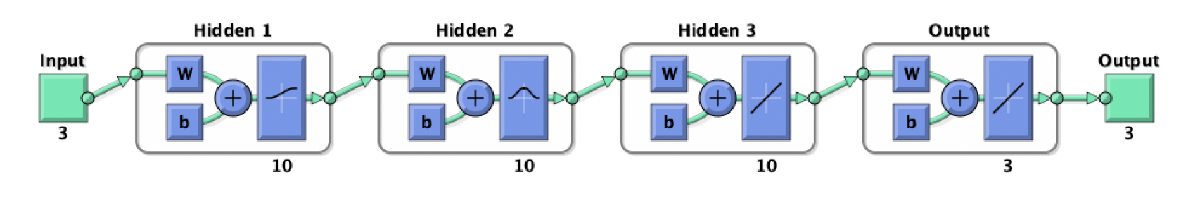

*Figure 1: Neural Network architecture comprised of three layers with ten nodes in each layer and a different activation unit for each layer.*

% build the neural network
net = feedforwardnet([10 10 10 ]);
net.layers{1}.transferFcn = 'logsig';
net.layers{2}.transferFcn = 'radbas';
net.layers{3}.transferFcn = 'purelin';
net.trainFcn = 'trainlm'

We are now going to train the NN for 1000 epochs of training. From the graphical user interface, open the plots for the performance, training state and the histogram of the error. Observe their evolution as a function of training epoch.

[net, tr] = train (net , input.' ,output.');

**Task 2. **What is the performance index chosen? Provide a plot of the performance and the error histogram at the end of 1000 epochs of training. How long does it take to train the NN for you? How many epochs were needed to produce accuracies on the order of ${10}^{-5}$?

plotperform(tr);
e=output.' - net(input.');
ploterrhist(e);

`Enter your text here.`

Once the NN is trained, the nonlinear model mapping obtained can be used for long-term predictions from any arbitrary initial condition $\mathbf{x}\left(0\right)$ by iteration of the following two steps:

- Use net output to predict the state $\mathbf{x}\left(\textrm{dt}\right)$

- Re-insert prediction of $\mathbf{x}\left(\textrm{dt}\right)$ into the net function to estimate the solution $t+\textrm{dt}$ into the future

This iterative mapping can produce a prediction for the future state as far into the future as desired. In what follows, the mapping is used to predict the Lorenz solutions eight time units into the future from for a given initial condition.

**Task 3.** Provide plots of the comparison between the time evolution of the Lorenz system simulated using the system equations with that predicted by the NN for two randomly chosen initial conditions. What can be observed? What can be concluded?

run("plotLoranzandNN.m") % produces plots for NN and Lorenz using 2 random initial conditions.

`Enter your text here.`

The choice of activation types, nodes in the layer and number of layers are arbitrary. It is trivial to make the network deeper and wider and enforce different activation units. Although the performance of the NN for the arbitrary choices made so far is quite remarkable.

**Task 4.** Try changing the NN architecture (add or decrease number of layers, change activation functions, vary size of hidden parameters). Can you decrease the network size or training time, while maintaining similar prediction accuracy? Justify your answers providing metrics and supportive figures.

net = feedforwardnet([10 10 10]); % specifies how many neurons per layer (columns = layers).

% Activation functions for each layer.
net.layers{1}.transferFcn = 'logsig';
net.layers{2}.transferFcn = 'radbas';
net.layers{3}.transferFcn = 'purelin';

net.trainFcn = 'trainlm'
[net,tr] = train(net,input.',output.');

run("plotLoranzandNN.m")
plotperform(tr);
e=output.' - net(input.');
ploterrhist(e);

## 2. Time series prediction with Long Short-Term Memory networks

In this part of the exercise, we will go over the time series forecasting using a long short-term memory (LSTM) network. The example trains an LSTM network to forecast the number of chickenpox cases given the number of cases in previous months. The dataset contains a single time series, with values corresponding to the number of cases. The time steps correspond to months. The output is a cell array, where each element is a single time step.

% Load the example data. 
data = chickenpox_dataset;
% Reshape the data to be a row vector.
data = [data{:}];

figure()
plot(data)
xlabel("Month")
ylabel("Cases")
title("Monthy Cases of Chickenpox")

We will now partition the training and test data. We start with a 90-10 split, i.e., training on the first 90% of the sequence and test on the remaining 10%.

numTimeStepsTrain = floor(0.9*numel(data));

dataTrain = data(1:numTimeStepsTrain+1);
dataTest = data(numTimeStepsTrain+1:end);

For a better fit and to prevent the training from diverging, we standardize the training data to have zero mean and unit variance. Once that is done, we organize the data for both training and testing in input-output pairs: we specify the input to be the the data sequence itself and the output to be the data sequence with values shifted by one time step. This way, at each time step of the input sequence, the LSTM network learns to predict the value of the next time step.

mu = mean(dataTrain);
sigma = std(dataTrain);

dataTrainStandardized = (dataTrain - mu) / sigma;
dataTestStandardized = (dataTest - mu) / sigma;

XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);
XTest  = dataTestStandardized(1:end-1);
YTest = dataTestStandardized(2:end);

We will now build the structure of the NN, starting with the LSTM layer to have 200 hidden units, and train it for 250 epochs of training. From the graphical user interface, observe the training progress. 

**Task 6. **What is the performance index chosen? Provide a plot of the performance index. How long does it take to train the LSTM for you?

% Define LSTM Network Architecture
  % Create an LSTM regression network. 

numFeatures = 1;
numResponses = 1;
numHiddenUnits = 200; 

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];

  % Specify the training options. 

options = trainingOptions('adam', ... % Set the solver to |'adam'|
    'MaxEpochs',250,'ValidationData',{XTest,YTest},'ValidationFrequency',2,...
    'GradientThreshold',1, ... %To prevent the gradients from exploding, set the gradient threshold to 1.
    'InitialLearnRate',0.005, ... %Specify the initial learn rate 0.005
    'LearnRateSchedule','piecewise', ... 
    'LearnRateDropPeriod',125,'LearnRateDropFactor',0.2, ... % drop the learn rate after 125 epochs by multiplying by a factor of 0.2.
    'Verbose',0,'Plots','training-progress');

net = trainNetwork(XTrain, YTrain, layers, options);

`Enter your text here.`

Let us use the trained model to make some predictions of chickenpox cases into the future.

**Task 7.** Plot the training time series with the forecasted values. What do you observe? Compare the forecasted values with the test data as well, for for infinite horizon prediction and one-step ahead prediction. What do you observe? What is the RMSE?

run("LTSMplot.m") % produces plots using trained data.

`Enter your text here.`

**Task 8.** Try changing the architecture of the LSTM by modifying the number of hidden layers. How does the size of hidden state impact the accuracy and training times? Try changing the max number of training epochs now. How does this impact accuracy and training times? Justify your answers providing metrics and supportive figures.

clear
close all
clc
Max_Epochs=250;
num_hidden_layers=200;
run('LSTMpredChickenpox_modify.m') % trains LSTM and plots

`Enter your text here.`

## `References`

[1] Brunton, S. L., & Kutz, J. N. (2022). [*Data-driven science and engineering: Machine learning, dynamical systems, and control*](https://databookuw.com). Cambridge University Press.

[2] Lorenz, E. N. (1963). Deterministic nonperiodic flow. *Journal of the Atmospheric Sciences*. **20** (2): 130–141.